# گام 11

BER_d01 = 1.0000e-05

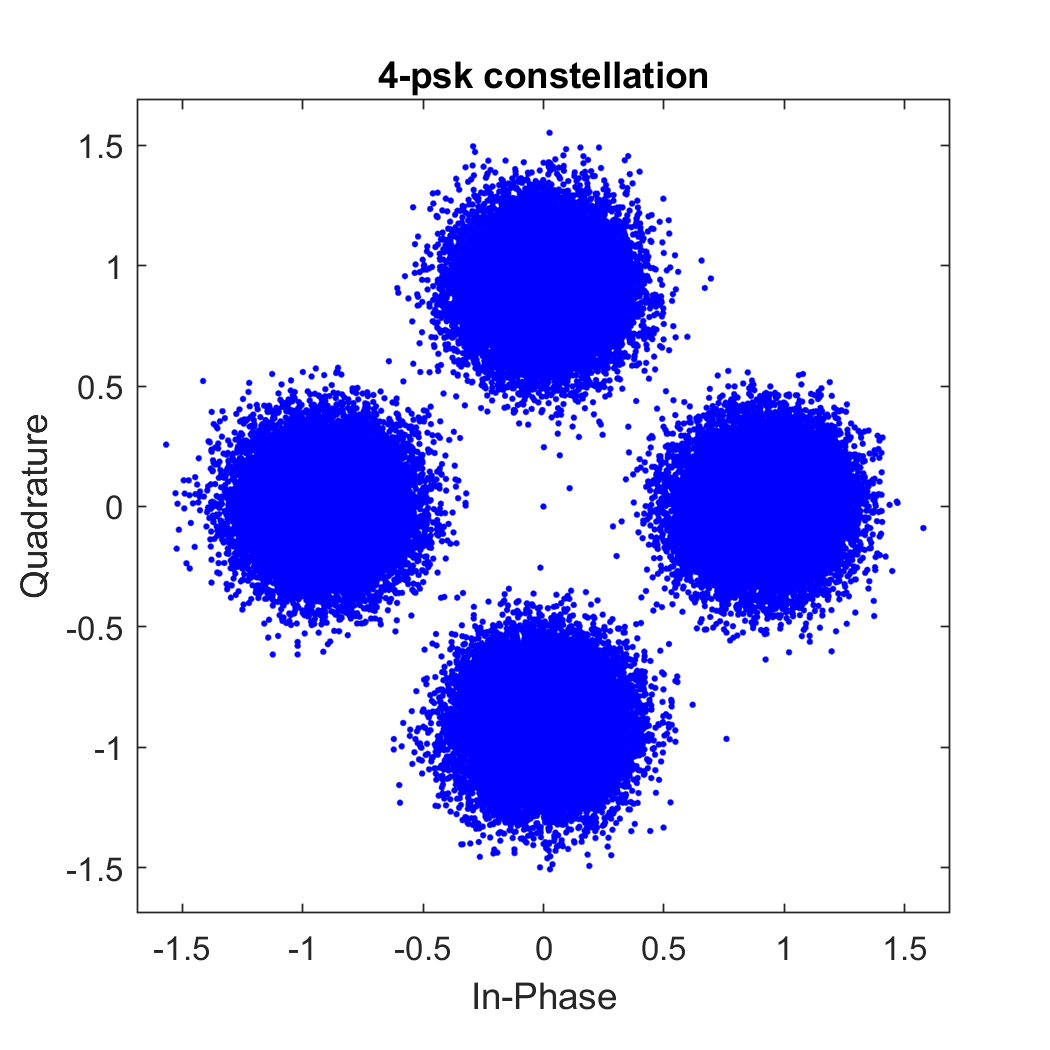

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_phase_offset = 0;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
plot_flag = 1;

chnl_delay_in_smpl = round(0.1*smpl_per_symbl);
BER_d01 = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_dB,fs,plot_flag)

BER_d05 = 0.2623

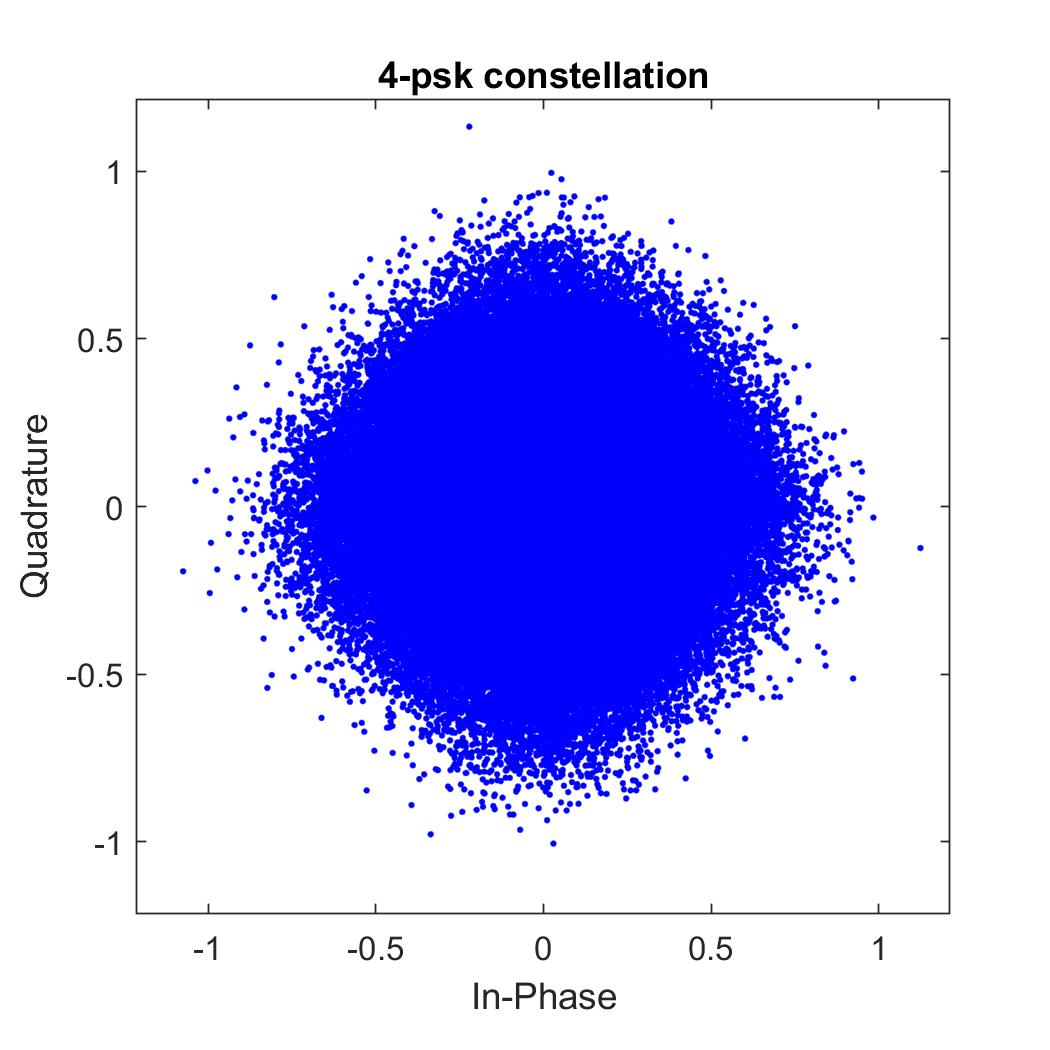

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_phase_offset = 0;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
plot_flag = 1;

chnl_delay_in_smpl = round(0.5*smpl_per_symbl);
BER_d05 = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_dB,fs,plot_flag)

BER_d08 = 0.5017

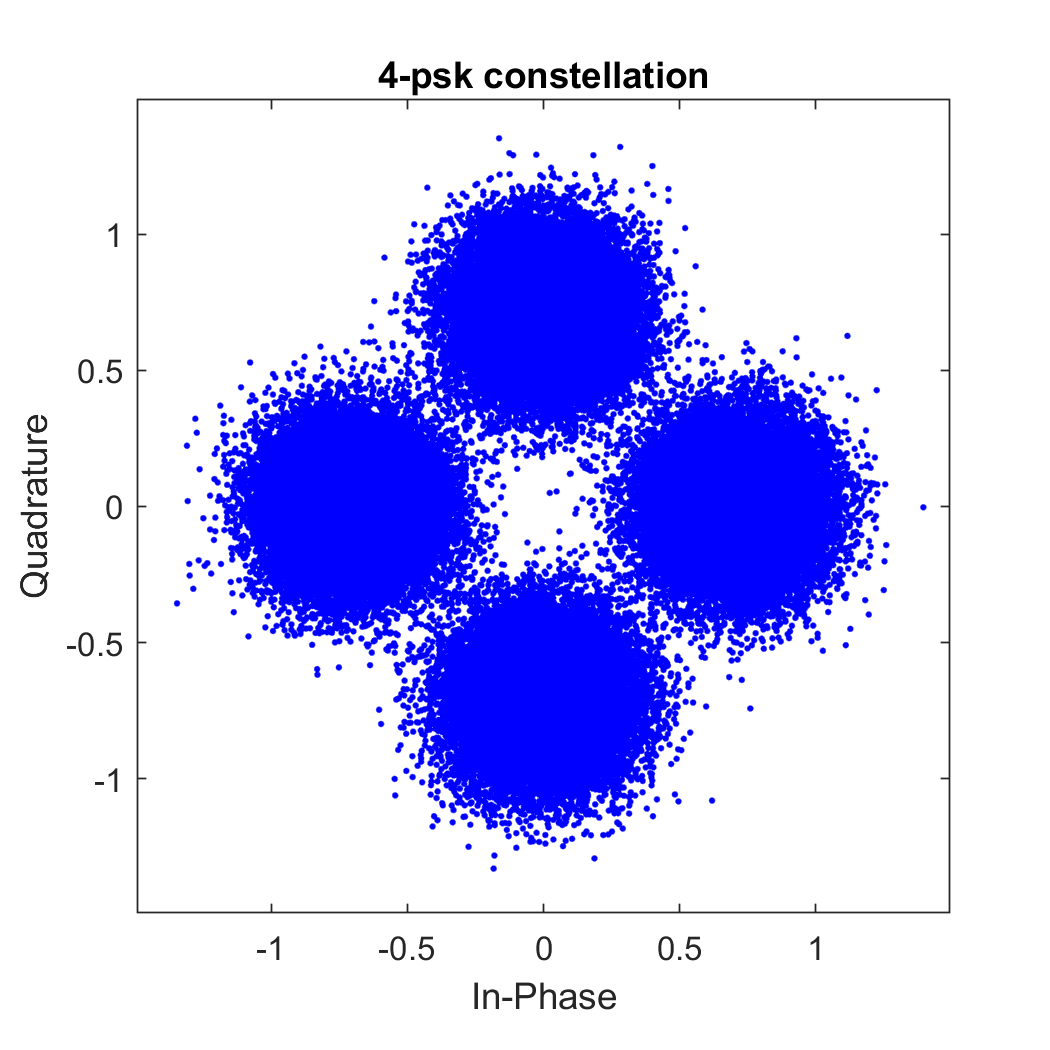

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_phase_offset = 0;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
plot_flag = 1;

chnl_delay_in_smpl = round(0.8*smpl_per_symbl);
BER_d08 = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_dB,fs,plot_flag)

#  گام 12

BER_d08 = 0.0261

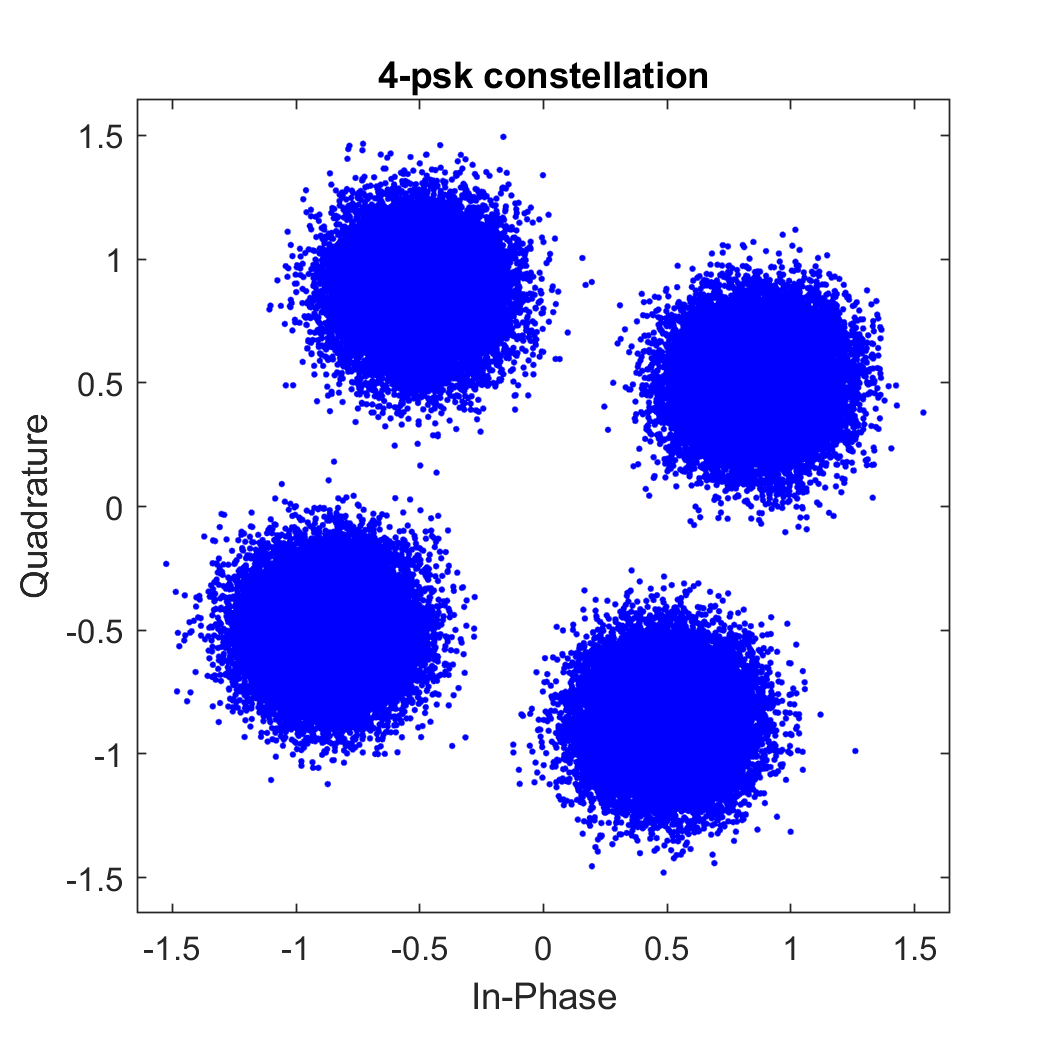

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
plot_flag = 1;
%phase offset
chnl_phase_offset = pi/6;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
chnl_delay_in_smpl = 0;
BER_d08 = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_dB,fs,plot_flag)

# گام 13

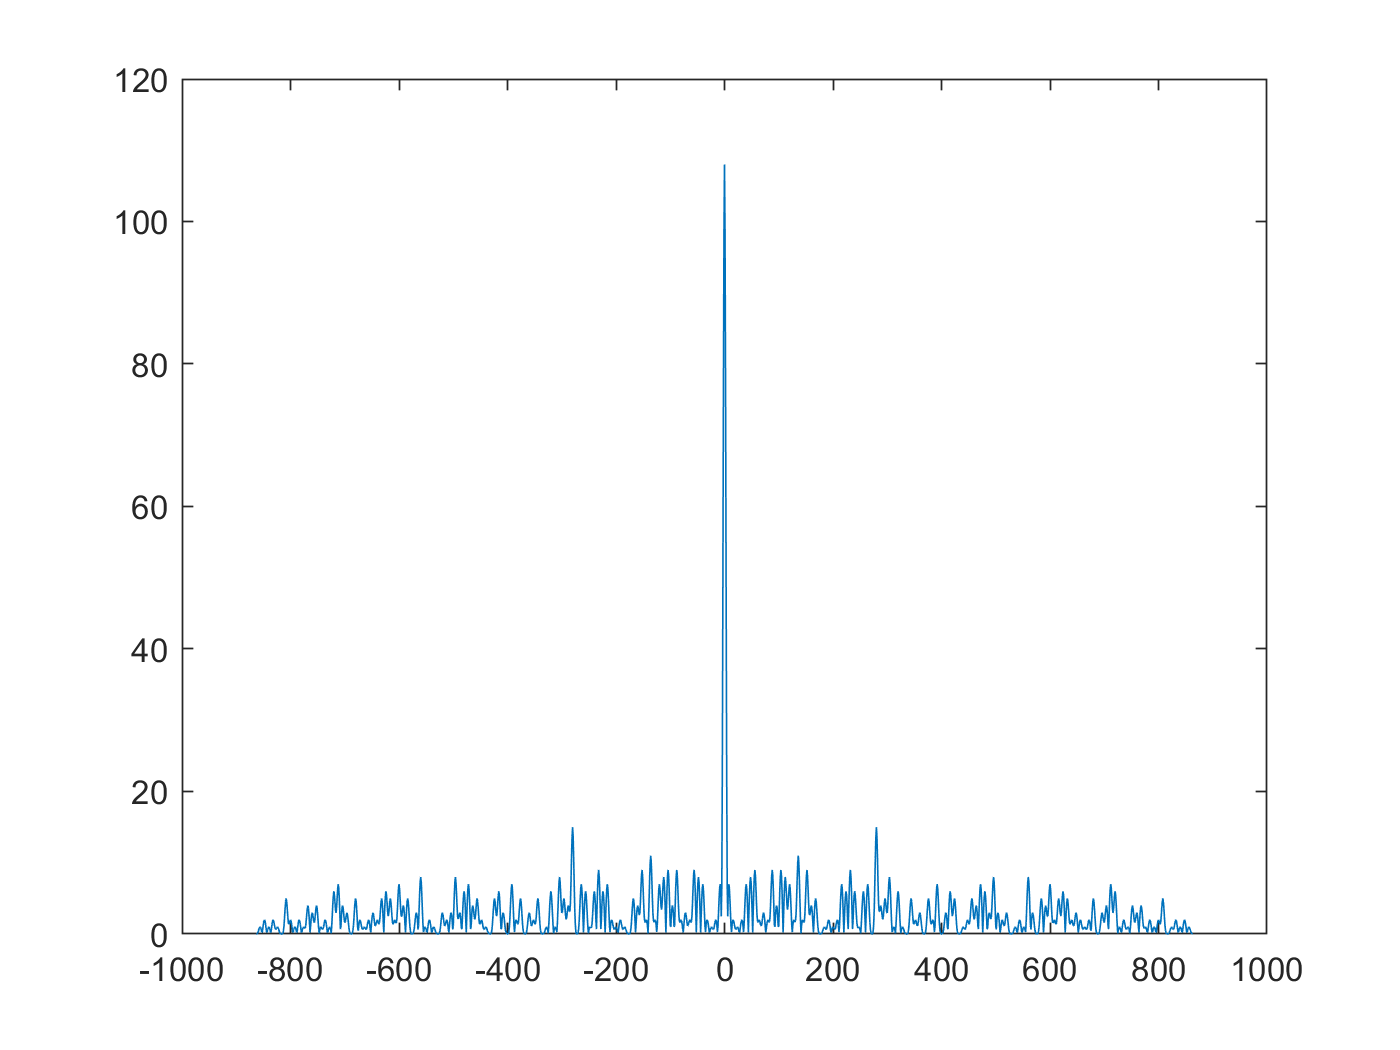

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_phase_offset = 0;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
%ask
chnl_delay_in_smpl = fix(0.5*smpl_per_symbl);

rx_alg = 1;
hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

b_tx = bit_gen(pkt_size, k);

b_gray = gray_code(k);
sym_idx = zeros(pkt_size, 1);
b_gray_dec = bi2de(b_gray, 'left-msb');
b_tx_dec = bi2de(b_tx, 'left-msb');
%add hder
b_tx_dec_hder = [hder_dec; b_tx_dec];

for c = 1:2^k
    sym_idx(b_tx_dec_hder == b_gray_dec(c)) = c;
end

[cons, Es_avg] = constellation(2^k, modulation);
mod_sym = cons(sym_idx);
[tx_smpl, cons_] = pulse_modulation(sym_idx, modulation, 2^k, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
%hder_smpl


hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
rx_smpl = tx_smpl_delayed * exp(1i * chnl_phase_offset);
Eb = Es_avg / k;
var_noise = Eb / power(10, (snr_dB / 10));
noise_smpl = (sqrt(var_noise/2) * randn(length(rx_smpl), 1) + 1i * sqrt(var_noise/2) * randn(length(rx_smpl), 1));
rx_smpl_noise = noise_smpl + rx_smpl;

[acorr, lag] = xcorr(hdr_smpl, hdr_smpl);
figure
plot(lag,abs(acorr))


[hder_corr, ~] = xcorr(hdr_smpl, rx_smpl_noise);
hder_auto_corr_peak = max(abs(acorr))

hder_auto_corr_peak = 108

[hder_corr_peak,idx_corr] = max(hder_corr)

hder_corr_peak =    1.0747e+02 + 1.3887e+00i


idx_corr = 800864

ang = angle(hder_corr_peak)

ang = 0.0129

idx_max = length(rx_smpl_noise) - idx_corr + 1

idx_max = 5



rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, 2^k, fs, smpl_per_symbl, pulse_name , rx_mode,0, 0);


det_bit = b_gray(det_sym_idx,:);
ber = sum(sum((det_bit(1:length(b_tx), :) ~= b_tx))) / (pkt_size * k)

ber = 0

# گام 14

clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_phase_offset = pi/6;
k = 2;
pulse_name = 'triangular';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
snr_dB = 10;
%ask
chnl_delay_in_smpl = fix(0.5*smpl_per_symbl);

rx_alg = 1;
hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

b_tx = bit_gen(pkt_size, k);

b_gray = gray_code(k);
sym_idx = zeros(pkt_size, 1);
b_gray_dec = bi2de(b_gray, 'left-msb');
b_tx_dec = bi2de(b_tx, 'left-msb');
%add hder
b_tx_dec_hder = [hder_dec; b_tx_dec];

for c = 1:2^k
    sym_idx(b_tx_dec_hder == b_gray_dec(c)) = c;
end

[cons, Es_avg] = constellation(2^k, modulation);
mod_sym = cons(sym_idx);
[tx_smpl, cons_] = pulse_modulation(sym_idx, modulation, 2^k, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
%hder_smpl
hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
rx_smpl = tx_smpl_delayed * exp(1i * chnl_phase_offset);
Eb = Es_avg / k;
var_noise = Eb / power(10, (snr_dB / 10));
noise_smpl = (sqrt(var_noise/2) * randn(length(rx_smpl), 1) + 1i * sqrt(var_noise/2) * randn(length(rx_smpl), 1));
rx_smpl_noise = noise_smpl + rx_smpl;


[hder_corr, ~] = xcorr(hdr_smpl, rx_smpl_noise);
[hder_corr_peak,idx_corr] = max(hder_corr)

hder_corr_peak =   93.0015 -52.6113i


idx_corr = 800864

idx_max = length(rx_smpl_noise) - idx_corr + 1

idx_max = 5

ang = angle(hder_corr_peak)

ang = -0.5148

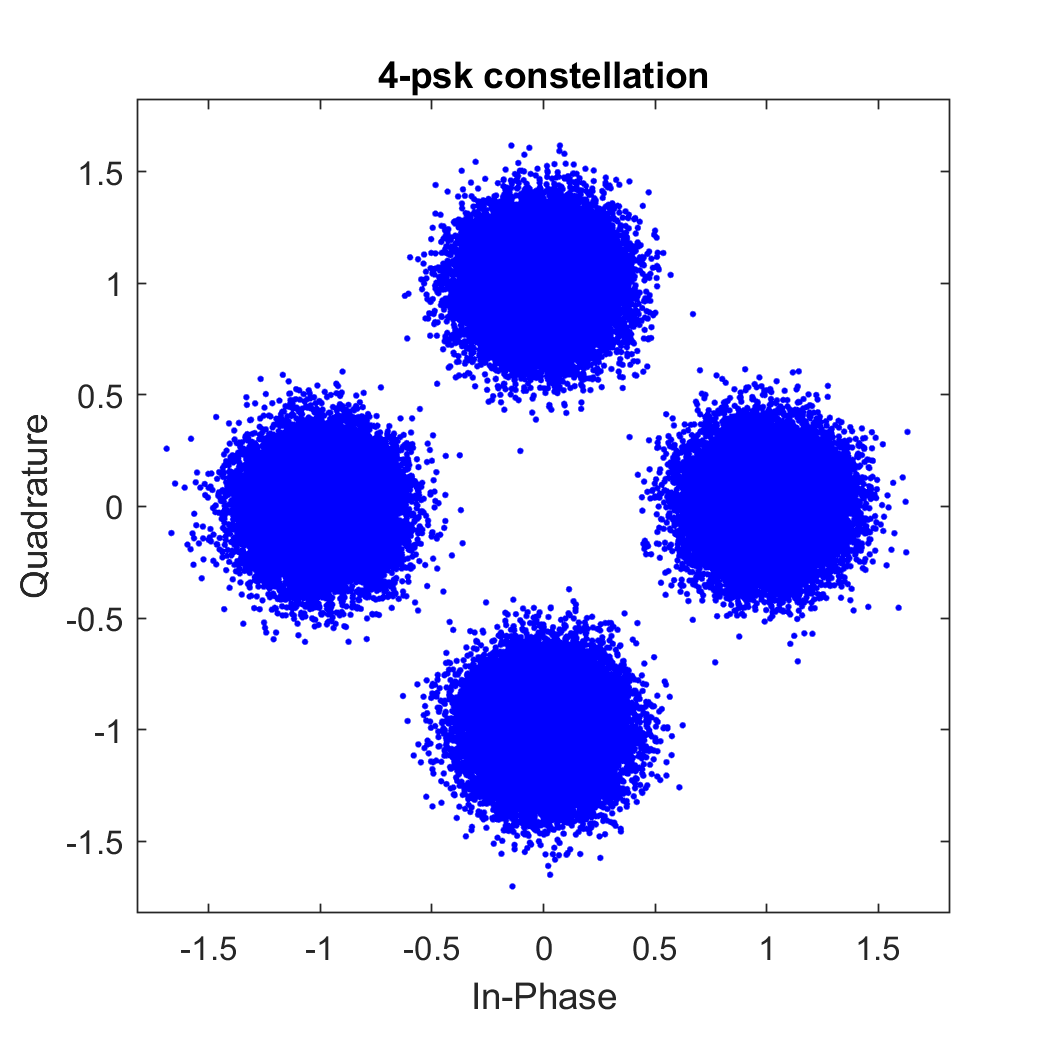


rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1) * exp(1i * ang);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, 2^k, fs, smpl_per_symbl, pulse_name , rx_mode,1, 0);



det_bit = b_gray(det_sym_idx,:);
ber = sum(sum((det_bit(1:length(b_tx), :) ~= b_tx))) / (pkt_size * k)

ber = 0

used functions

function [ber] = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_db,fs,plot_flag)
    b_tx = bit_gen(pkt_size, k);
    flg_gray_encode=1;
    if flg_gray_encode == 1
        b_gray = gray_code(k);
        sym_idx = zeros(pkt_size, 1);
        b_gray_dec = bi2de(b_gray, 'left-msb');
        b_tx_dec = bi2de(b_tx, 'left-msb');
        for c = 1:2^k
            sym_idx(b_tx_dec == b_gray_dec(c)) = c;
        end
    else
        sym_idx = bi2de(b_tx,'left-msb')+1;
    end
    [cons, Es_avg] = constellation(2^k, modulation);
    mod_sym = cons(sym_idx);
    [tx_smpl, cons_] = pulse_modulation(sym_idx, modulation, 2^k, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
    
    % if pkt_size==10
    %     plot( real(tx_smpl))
    %     hold on
    %     plot( imag(tx_smpl))
    %     hold off
    %     legend('real part', 'imaginary part', 'Location', 'south')
    % end
    
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
    rx_smpl = tx_smpl_delayed * exp(1i * chnl_phase_offset);
    Eb = Es_avg / k;
    var_noise = Eb / power(10, (snr_db / 10));
    noise_smpl = (sqrt(var_noise/2) * randn(length(rx_smpl), 1) + 1i * sqrt(var_noise/2) * randn(length(rx_smpl), 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    
    
    rx_smpl = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, 2^k, fs, smpl_per_symbl, pulse_name , rx_mode,plot_flag, 0);
    
    
    if flg_gray_encode == 1
        det_bit = b_gray(det_sym_idx,:);
    else
         det_bit = de2bi(det_sym_idx-1, 'left-msb');
    end
    ber = sum(sum((det_bit(1:length(b_tx), :) ~= b_tx))) / (pkt_size * k);
end
function [b] = bit_gen(N, k)
b = int32(randi([0,1],N,k));
end

function [b_gray] = gray_code(k)
    b_gray = ones(2^k, k);
    b_gray(1:2^(k-1), 1) = 0;
    if k ~= 1
        tmp = gray_code(k-1);
        b_gray(1:2^(k-1), 2:k) = tmp;
        b_gray(2^(k-1) + 1:2^k, 2:k) = flip(tmp, 1);
    end
end

function [cons, Es_avg] = constellation(M, modulation)
    l = (1:M)';
    switch modulation
        case 'pam'
            cons = 2*l - 1 - M;
        case 'psk'
            cons = cos(2*pi*(l-1)/M) +1i*sin(2*pi*(l-1)/M);
        case 'qam'
            M1 = 2^ceil(log2(sqrt(M)));
            M2 = 2^floor(log2(sqrt(M)));
            cons1 = -(M1-1):2:(M1-1);
            cons2 = -(M2-1):2:(M2-1);
            cons = cons1 + 1i*cons2';
            for i = 1:size(cons, 2)
                if mod(i, 2) == 0
                    cons(:, i) = cons(end:-1:1, i);
                end
            end
            cons = cons(:);
        otherwise
            disp('invalid modulation')
    end
    Es_avg = sum(abs(cons).^2)/M;
    cons = cons/sqrt(Es_avg);
    Es_avg = 1;
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
    t = (0:smpl_per_symbl-1).'/fs;
    Ts = smpl_per_symbl/fs;
    switch pulse_name
        case 'rectangular'
            p = 1/sqrt(Ts).*(t >= 0 & t<= Ts);
        case 'triangular'
            p = max(Ts/2 - abs(t - Ts/2), 0);
        case 'sine'
            p = sin(pi/Ts*t).*(t >= 0 & t<= Ts);
        otherwise
    end
    p = p/sqrt(sum(p.^2));
end

function [y] = upsmpl(x, N)
    y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
    for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
        y(i) = x((i - 1)/N + 1);
    end
end

function [tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_shape_mode, varargin)
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin);
    [cons, ~] = constellation(M, modulation);
    s = cons(sym_idx);
    switch pulse_shape_mode
        case 'kron'
            tx_out = kron(s, p);
        case 'conv'
            s_zero_pad = upsmpl(s,length(p));
            tx_out = conv(s_zero_pad,p).';
        otherwise
    end
    tx_smpl = tx_out;
end

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
    if mod(length(rx_smpl), smpl_per_symbl) == 0
        rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);
    else
        rx_sym = zeros(fix(length(rx_smpl)/smpl_per_symbl) + 1, 1);
        rx_smpl = [rx_smpl; zeros(smpl_per_symbl - mod(length(rx_smpl), smpl_per_symbl), 1)];
    end
    switch rx_mode
        case 'correlator'
            for c = 1:smpl_per_symbl:length(rx_smpl)
                rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
            end
        case 'matched_filter'
            tmp = conv(rx_smpl, flip(conj(p)), 'valid');
            rx_sym = tmp(1:smpl_per_symbl:end);
        otherwise
    end
end

function [det_sym] = min_dist_detector(rx_sym, constellationn)
    [~,idx] = min(abs(constellationn-rx_sym.'));
    det_sym = constellationn(idx);
end

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode,plot_flag, varargin)
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin);
    rx_sym = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode);
    if plot_flag == 1
        scatterplot(rx_sym)
        title([num2str(M), '-', modulation, ' constellation'])
    end
    [cons, ~] = constellation(M, modulation);
    [~,det_sym_idx] = min(abs(cons-rx_sym.'));
    det_sym_idx = det_sym_idx.';
    rx_sym = cons(det_sym_idx);
     
end


